# DL draft

(Single cell, Section 1)

github@hnxj; github@dynasim

## Initialization

clear;close all;clc;
PathToDynaSim = 'D:\Works\Computational'; % Change it based on your local path for dynasim
cd(PathToDynaSim);
addpath(genpath('DynaSim'));
cd('DynaSim');

## Single population with signle cell optimaztion examples

RunDuration = 500; % In ms (miliseconds)
study_dir = 'dlModels/HHNS1';

spec = dsCheckSpecification('HH');
vary = {'HH','Eleak',[-70 -60 -50 -40 -30]};
solver_options = {'tspan',[0 RunDuration],'solver','rk1','dt',.01,'compile_flag',0,'verbose_flag',1};
data = dsSimulate(spec,'vary',vary,solver_options{:});


PREPARING STUDY:

PREPARING SOLVER:
Changing directory to D:\Works\Computational\DynaSim\solve
Saving params.mat
Creating solver file: D:\Works\Computational\DynaSim\solve\solve_ode_20230624092849_848.m
Changing directory back to D:\Works\Computational\DynaSim

SIMULATING MODEL:
Solving system using D:\Works\Computational\DynaSim\solve\solve_ode_20230624092849_848.m
Changing directory to D:\Works\Computational\DynaSim\solve
Saving model parameters: D:\Works\Computational\DynaSim\solve\params.mat

Running simulation 1/5 (solver='rk1', dt=0.01, tspan=[0 500]) ...
Total Memory Used <= 1 GB 
Elapsed time: 0.1 seconds.
Changing directory to D:\Works\Computational\DynaSim\solve
Saving model parameters: D:\Works\Computational\DynaSim\solve\params.mat

Running simulation 2/5 (solver='rk1', dt=0.01, tspan=[0 500]) ...
Total Memory Used <= 1 GB 
Elapsed time: 0.1 seconds.
Changing directory to D:\Works\Computational\DynaSim\solve
Saving model parameters: D:\Works\Computational\DynaSim\solve\par

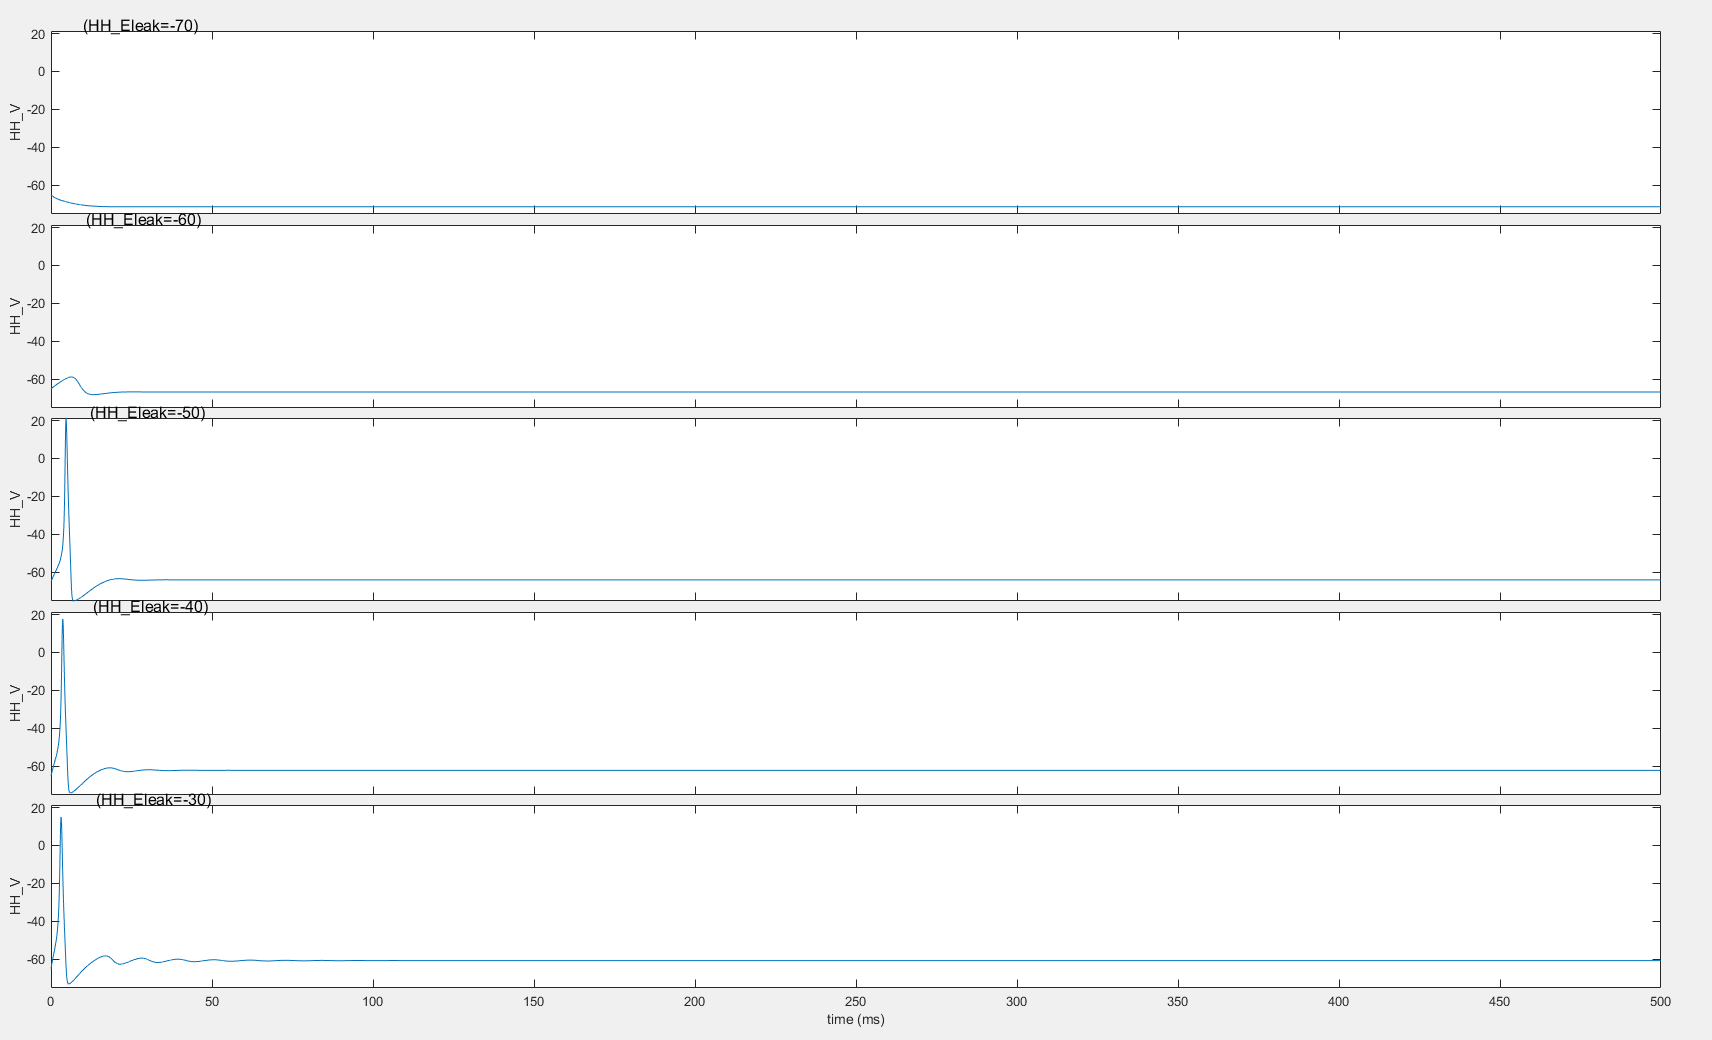

dsPlot(data,'plot_type','waveform');

## Passing to DynaLearn

dl = DynaLearn(spec, study_dir, 'raw', 'HHNS1');
dl.dlSave();

## Load (ONLY IF ALREADY EXISTS)

id = 1; % 1, 2, ...
dl = DynaLearn.dlLoader(char("dlModels/HHNS" + num2str(id)));

## Define optimization parameters

param_file = fullfile(study_dir, 'params.mat');
load(param_file, 'p');
fprintf('Initial Eleak: %g\n', p.HH_ileak_Eleak);

target_RMP = -62;

% Define optimization parameters
dlInputParameters = {dlNullInputs(RunDuration)}; % Null inputs (no external stimulation).
dlOutputParameters = {['HH', '_V'], 1, [100 RunDuration], 'av'}; % 'av' is average voltage
dlTargetParameters = {{'MQE', 1, target_RMP, 1}}; % Format: (1)Mode;(2)Output indices;(3)Target value;(4)Weight in loss equation

% Define training options
dlTrainOptions = containers.Map(); % Train options; MUST be a map data structure
dlTrainOptions('dlLambda') = 1e-3; % Fitting/Learning rate
dlTrainOptions('dlEpochs') = 1; % Total iterations 
dlTrainOptions('dlEnhancedMomentum') = 0.3;
dlTrainOptions('dlTrainIncludeList') = ["_Eleak"];
dlTrainOptions('dlCheckpointCoefficient') = 1.1;
dlTrainOptions('dlUpdateVerbose') = 1;
dl.dlTrain(dlInputParameters, dlOutputParameters, dlTargetParameters, dlTrainOptions);
dl.dlSimulate();
dl.dlPlotAllPotentials('lfp');

dlTrainOptions = containers.Map(); % Train options; MUST be a map data structure
dlTrainOptions('dlLambda') = 1e-2; % Fitting/Learning rate
dlTrainOptions('dlEpochs') = 200; % Total iterations 
dlTrainOptions('dlEnhancedMomentum') = 0.4;
dlTrainOptions('dlTrainIncludeList') = ["_Eleak"];
dlTrainOptions('dlCheckpointCoefficient') = 1.5;
dlTrainOptions('dlUpdateVerbose') = 1;
dl.dlTrain(dlInputParameters, dlOutputParameters, dlTargetParameters, dlTrainOptions);

dl.dlPlotBatchErrors(1);
dl.dlLoadOptimal();
dl.dlSimulate();
dl.dlPlotAllPotentials('lfp');
optimal_param_file = fullfile(study_dir, 'Optimalparams.mat');
load(optimal_param_file, 'p');
fprintf('Optimal Eleak: %g\n', p.HH_ileak_Eleak);

## END